# Machine Learning with MATLAB

Digital Twin & Automation

# Linear Regression

## Example 1: Fit with Linear Regression 

**Data Acquisition**

- Feature: One-Dimension,  p=1

- True value: ytrue = 2X+3

x = randn(100,1);
y = x*2 + 3+randn(100,1);

**Fit Linear Regression**

mdl = fitlm(x,y)

mdl = 선형 회귀 모델:
    y ~ 1 + x1

추정된 계수:
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________

    (Intercept)     3.003      0.093885    31.986    1.1527e-53
    x1              2.108      0.094114    22.398    2.4844e-40


관측값 개수: 100, 오차 자유도: 98
RMS 오차: 0.936
결정계수: 0.837, 수정된 결정계수: 0.835
상수 모델에 대한 F-통계량: 502, p-값 = 2.48e-40

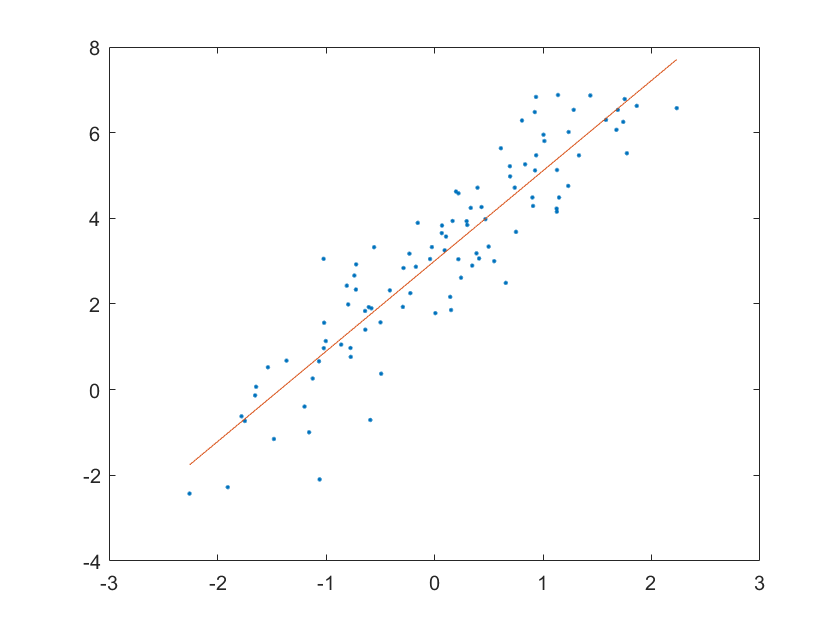


% Plot prediction
plot(x,y,'.',x,mdl.Fitted, '-')

**Anlayze Linear Regression**

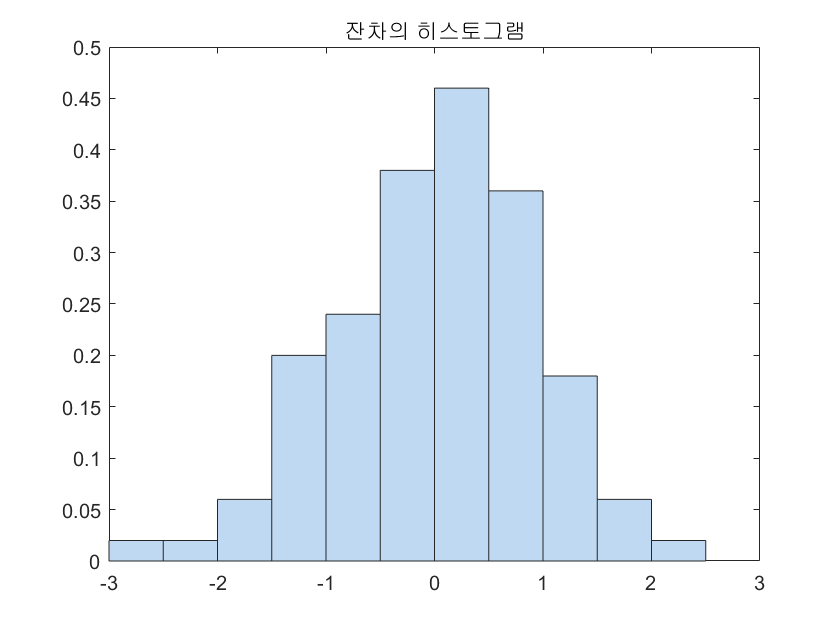

% Plot residual histogram
plotResiduals(mdl)


% From remove outlier from histogram
outl = find(abs(mdl.Residuals.Raw) > 2);
mdl.Residuals.Raw(outl)

ans =    -2.4637
   -2.8673
    2.2073



% Fit with outlier removed
mdl2 = fitlm(x,y,'Exclude',outl)

mdl2 = 선형 회귀 모델:
    y ~ 1 + x1

추정된 계수:
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________

    (Intercept)     3.0383     0.085466     35.55    1.1079e-56
    x1               2.081     0.085466    24.348    1.2728e-42


관측값 개수: 97, 오차 자유도: 95
RMS 오차: 0.836
결정계수: 0.862, 수정된 결정계수: 0.86
상수 모델에 대한 F-통계량: 593, p-값 = 1.27e-42

**Predict with Test data**

% Ypredict and confidence interval
Xnew=2;
% y=7 %true
[Ynew,YnewI]=predict(mdl2,Xnew)

Ynew = 7.2002

YnewI =     6.8384    7.5620


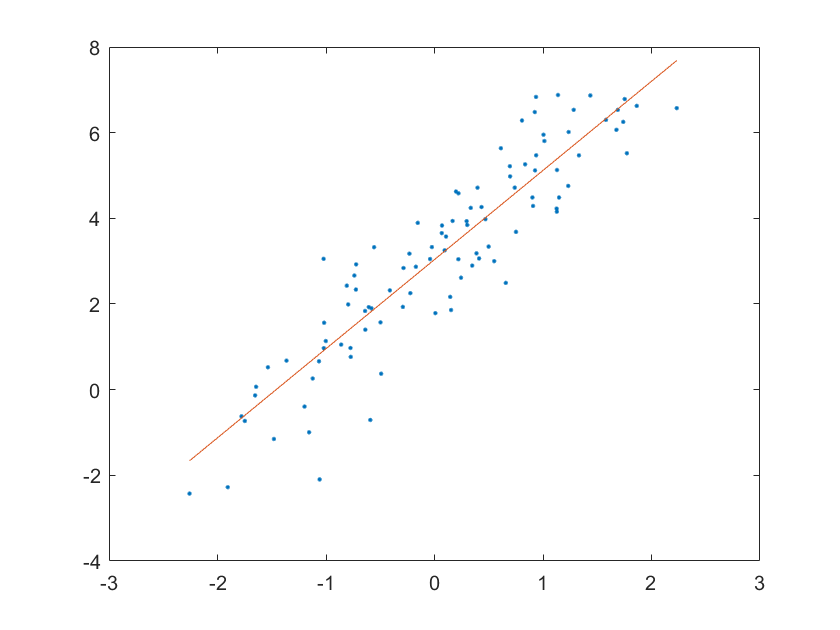


% Plot prediction
plot(x,y,'.',x,mdl2.Fitted, '-')

## Example 2: Predict Car MPG

Find linear relationship of  MPG(연비) with   Weight & Displacement

Then, Predict MPG for a car with Weight=3000 , Displacement=300

**Data Acquisition**

-  Dependet Variable:  MPG

- Independet Variables: Weight, Displacement

clear
load carsmall

tbl = table(MPG,Weight, Displacement);  % table type

**Fit  Linear Regression**

mdl = fitlm(tbl,'MPG~Weight+Displacement')

mdl = 선형 회귀 모델:
    MPG ~ 1 + Weight + Displacement

추정된 계수:
                     Estimate        SE         tStat       pValue  
                    __________    _________    _______    __________

    (Intercept)         46.925       2.0858     22.497    6.0509e-39
    Weight          -0.0068422    0.0011337    -6.0353    3.3838e-08
    Displacement     -0.014593    0.0082695    -1.7647      0.080968


관측값 개수: 94, 오차 자유도: 91
RMS 오차: 4.09
결정계수: 0.747, 수정된 결정계수: 0.741
상수 모델에 대한 F-통계량: 134, p-값 = 7.22e-28

mdl.CoefficientNames

ans = 1×3 cell 배열
    {'(Intercept)'}    {'Weight'}    {'Displacement'}


mdl.Coefficients.Estimate

ans =    46.9247
   -0.0068
   -0.0146


**Analyze, Modify**

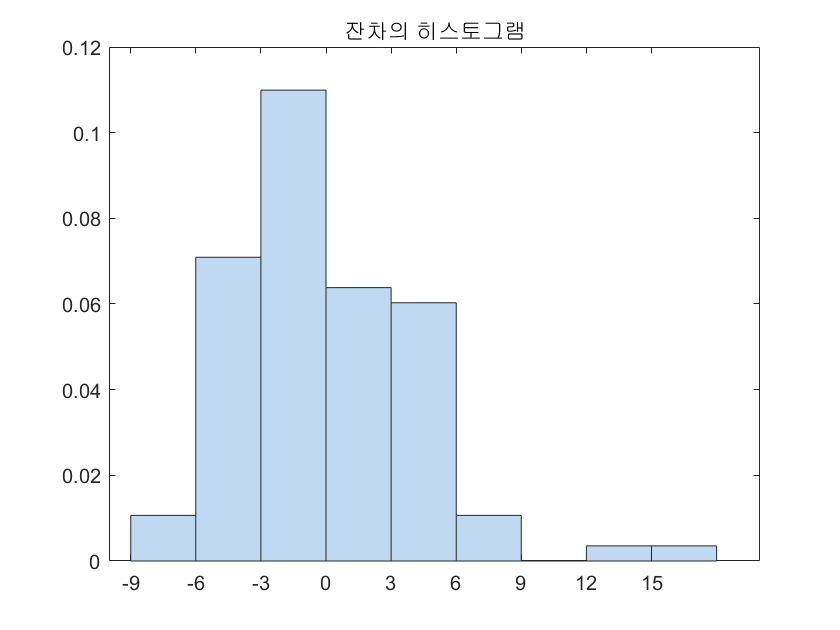

plotResiduals(mdl)


% Remove outlier
outl = find((mdl.Residuals.Raw) > 9);

% Fit with outlier removed
mdl2 = fitlm(tbl,'MPG~Weight+Displacement','Exclude',outl)

mdl2 = 선형 회귀 모델:
    MPG ~ 1 + Weight + Displacement

추정된 계수:
                     Estimate         SE         tStat       pValue  
                    __________    __________    _______    __________

    (Intercept)         45.548        1.8056     25.226    2.5559e-42
    Weight          -0.0062503    0.00097845    -6.3879    7.4767e-09
    Displacement     -0.018035     0.0071414    -2.5255      0.013324


관측값 개수: 92, 오차 자유도: 89
RMS 오차: 3.51
결정계수: 0.796, 수정된 결정계수: 0.792
상수 모델에 대한 F-통계량: 174, p-값 = 1.78e-31

mdl2.Coefficients.Estimate

ans =    45.5477
   -0.0063
   -0.0180


**Predict**

Detailed look at the interactions 

% Ypredict and confidence interval
Xnew=[3000 300]; 
[Ynew,YnewI]=predict(mdl2,Xnew)

Ynew = 21.3863

YnewI =    19.8515   22.9211


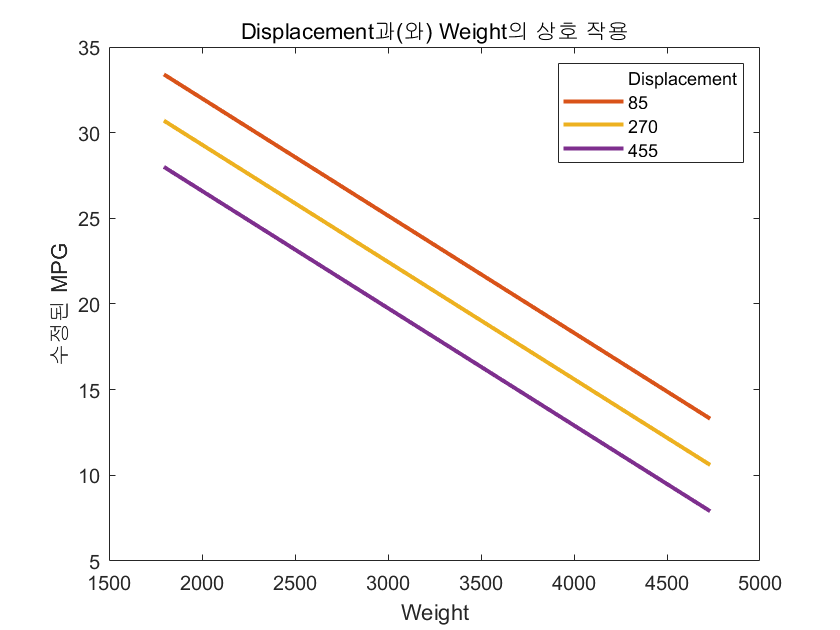


plotInteraction(mdl,'Displacement','Weight','predictions')

# Exercise

## Exercise 1 :  Using Gradient Descent

**Linear Regression Using Gradient Descent**

Hypothesis. 

To find the parameters, repeat until convergence

where

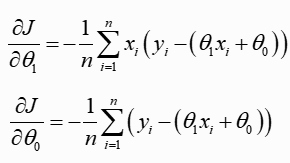

**Data Acquisition**

Feature: One-Dimension,  p=1

True: y = 2X+3

N=100;
X = randn(N,1);
Y = X*2 + 3+randn(N,1);



**Fit Linear Regression:  Gradient Descent**

% dJ/dx
lamda=0.1  % learning rate

lamda = 0.1000


% Initialization for t0, t1
t0=0.5;
t1=0.5;
e=1;
itrN=1000;
k=0

k = 0


%%% ADD your code here
while(e>0.001 || k<itrN)
    % h=_______
    % dJt1=_______
    % dJt0=_______
    % t1_new=_______
    % t0_new=_______
    e=0.5*(abs((t1_new-t1))+abs((t0_new-t0)));
    t1=t1_new;
    t0=t0_new;
    k=k+1;
end


% Predicted hypothesis y(x)
% ypred=___________ %%% ADD your code here


disp('optimal paraterms are')

optimal paraterms are


t1

t1 = 2.0880

t0

t0 = 2.8072



% MATLAB fit linear 
% mdl = ____________   %%% ADD your code here

mdl = 선형 회귀 모델:
    y ~ 1 + x1

추정된 계수:
                   Estimate      SE       tStat       pValue  
                   ________    _______    ______    __________

    (Intercept)     2.8072       0.103    27.254    1.5559e-47
    x1               2.088     0.10366    20.143    1.2951e-36


관측값 개수: 100, 오차 자유도: 98
RMS 오차: 1.03
결정계수: 0.805, 수정된 결정계수: 0.803
상수 모델에 대한 F-통계량: 406, p-값 = 1.3e-36

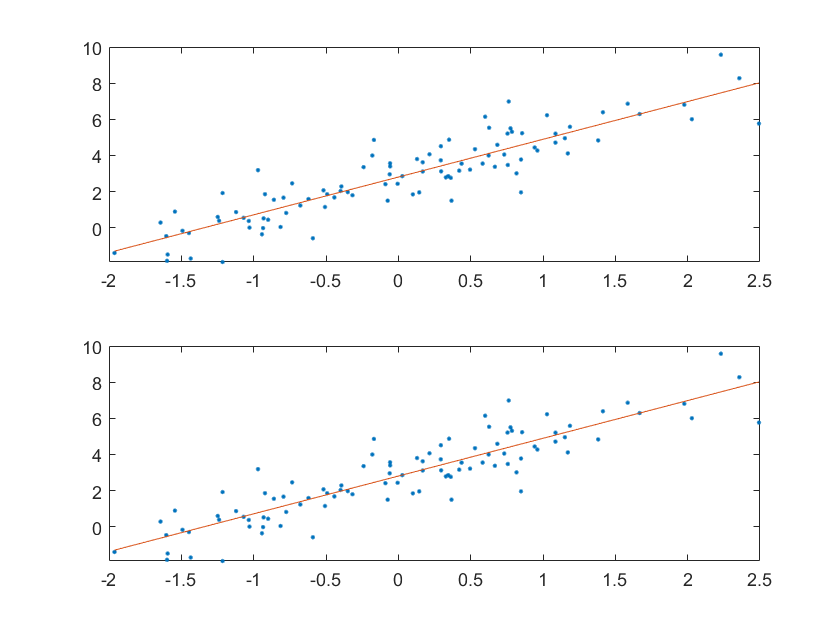



% Plot and compare predictions
figure
subplot(2,1,1)
plot(X,Y,'.',X,mdl.Fitted, '-')
subplot(2,1,2)
plot(X,Y,'.',X,ypred, '-')

## Exercise 2 :  Linear Regression with p=2

Find the linear regression. Remove Outlier and predict a test value Xtest=[2;1];.  You can use MATLAB fitlm()

- Feature: 2-Dimensions,  p=2

- True value: y = 2*X1+4*X2+3

**Data Acquisition**

X = randn(100,2);
y = X*[2;4] + 3+ randn(100,1);

% Your code goes here
% Your code goes here

**Fit  Linear Regression**

**Analyze, Modify**

% Remove outlier



**Predict**

Predict for a Test value

## Exercise 3:  Linear Regression with p=4

Find linear relationship of 

- MPG ~ 1 + Acceleration + Displacement + Horsepower + Weight 

Choose a test data and predict

**Data Acquisition**

% load carsmall




**Fit  Linear Regression**

**Analyze, Modify**

% Remove outlier



**Predict**

Predict for a Test value